## Setup and Columns Defining

clc; 
clear; 
close all;
%This is the folder where all your C-MAPSS files are stored
baseDir = "C:\Users\salma\Desktop\ML for Eng apps\Project\6.+Turbofan+Engine+Degradation+Simulation+Data+Set\6. Turbofan Engine Degradation Simulation Data Set\CMAPSSData";

%% Column names
columns = { ...
    'unit_number','time_in_cycles','setting_1','setting_2','TRA','T2','T24','T30','T50','P2','P15','P30','Nf', ...
    'Nc','epr','Ps30','phi','NRf','NRc','BPR','farB','htBleed','Nf_dmd','PCNfR_dmd','W31','W32'};
%% Columns to drop
dropVars1 = {'Nf_dmd','PCNfR_dmd','P2','T2','TRA','farB','epr'};
dropVars2 = {'unit_number','setting_1','setting_2'};   

rng(42);


## Preprocessing

trainAll = table();

for idx = 1:4
    trainFile = fullfile(baseDir, "train_FD00" + idx + ".txt");

    M = readmatrix(trainFile);
    if size(M,2) >= 28
        M(:,27:28) = [];
    end

    T = array2table(M, 'VariableNames', columns);

    % Drop selected sensors
    T(:, dropVars1) = [];

    % Compute normalized RUL: time_in_cycles / max(time_in_cycles per unit)
    u = T.unit_number;
    c = T.time_in_cycles;

    maxCyclePerRow = splitapply(@max, c, findgroups(u));

    grp = findgroups(u);
    maxCyclePerRowExpanded = maxCyclePerRow(grp);

    T.RUL = c ./ maxCyclePerRowExpanded;

    T(:, dropVars2) = [];

    trainAll = [trainAll; T];

    fprintf("Processed train_FD00%d.txt, number of rows: %d\n", idx, height(T));
end

Processed train_FD001.txt, number of rows: 20631
Processed train_FD002.txt, number of rows: 53759
Processed train_FD003.txt, number of rows: 24720
Processed train_FD004.txt, number of rows: 61249


## Splitting Features from Target 

%% Split X/y Label
y = trainAll.RUL;
X = removevars(trainAll, "RUL");

## Train and Validation Split


k = 5;
cv = cvpartition(height(X), 'KFold', k);

foldRMSE = zeros(k, 1);

for f = 1:k
    % Split 
    X_train = X(training(cv, f), :);
    y_train = y(training(cv, f));
    X_valid = X(test(cv, f),     :);
    y_valid = y(test(cv, f));

    % Train 
    rf_fold = TreeBagger(300, X_train, y_train, ...
        'Method', 'regression', ...
        'OOBPrediction', 'Off');

    % Validate 
    y_pred_valid = predict(rf_fold, X_valid);
    foldRMSE(f)  = sqrt(mean((y_valid - y_pred_valid).^2));

    fprintf("Fold %d RMSE: %.4f\n", f, foldRMSE(f));
end

Fold 1 RMSE: 0.0624
Fold 2 RMSE: 0.0631
Fold 3 RMSE: 0.0624
Fold 4 RMSE: 0.0623
Fold 5 RMSE: 0.0626



fprintf("\nMean CV RMSE : %.4f\n", mean(foldRMSE));


Mean CV RMSE : 0.0626


fprintf("Std  CV RMSE : %.4f\n",  std(foldRMSE));

Std  CV RMSE : 0.0003


## TRAIN RANDOM FOREST REGRESSOR

nTrees = 300;

rf = TreeBagger(nTrees, X_train, y_train, ...
    'Method','regression', ...
    'OOBPrediction','On');
% Validate
y_pred_valid = predict(rf, X_valid);
mse_valid = mean((y_valid - y_pred_valid).^2);
fprintf("Validation MSE (holdout 20%%): %.6f\n", mse_valid);

Validation MSE (holdout 20%): 0.003922



%% Save model
modelFile = fullfile(baseDir, "random_forest_model.mat");
save(modelFile, "rf");
fprintf("Saved model to: %s\n", modelFile);

Saved model to: C:\Users\salma\Desktop\ML for Eng apps\Project\6.+Turbofan+Engine+Degradation+Simulation+Data+Set\6. Turbofan Engine Degradation Simulation Data Set\CMAPSSData\random_forest_model.mat



%% Load model 
clear rf
S = load(modelFile, "rf");
rf = S.rf;


## Test data Preprocessing

testAll = table();

for idx = 1:4
    testFile = fullfile(baseDir, "test_FD00" + idx + ".txt");
    rulFile  = fullfile(baseDir, "RUL_FD00" + idx + ".txt");

    Mtest = readmatrix(testFile);
    Mrul  = readmatrix(rulFile);

    if size(Mtest,2) >= 28
        Mtest(:,27:28) = [];
    end

    Ttest = array2table(Mtest, 'VariableNames', columns);
    Ttest(:, dropVars1) = [];

    u = Ttest.unit_number;
    c = Ttest.time_in_cycles;

    uniqueUnits = unique(u, 'stable');
    eolPerRow = zeros(height(Ttest), 1);

    for k = 1:numel(uniqueUnits)
        unitId = uniqueUnits(k);
        idxRows = (u == unitId);

        eolTemp = Mrul(unitId, 1);

        eolPerRow(idxRows) = eolTemp;
    end

    maxCyclePerUnit = splitapply(@max, c, findgroups(u));
    grp = findgroups(u);
    maxCycleExpanded = maxCyclePerUnit(grp);

    Ttest.RUL = c ./ (maxCycleExpanded + eolPerRow);

    Ttest(:, dropVars2) = [];

    testAll = [testAll; Ttest]; 

    fprintf("Processed test_FD00%d.txt, number of rows: %d\n", idx, height(Ttest));
end

Processed test_FD001.txt, number of rows: 13096
Processed test_FD002.txt, number of rows: 33991
Processed test_FD003.txt, number of rows: 16596
Processed test_FD004.txt, number of rows: 41214


## Test MSE evaluation

y_test = testAll.RUL;
X_test = removevars(testAll, "RUL");

y_pred_test = predict(rf, X_test);
mse_test = mean((y_test - y_pred_test).^2);
fprintf("Test MSE (FD001..FD004): %.6f\n", mse_test);

Test MSE (FD001..FD004): 0.004773


## Plot per Unit

fd = 2;
testFile = fullfile(baseDir, "test_FD00" + fd + ".txt");
rulFile  = fullfile(baseDir, "RUL_FD00" + fd + ".txt");

M = readmatrix(testFile);
Mrul = readmatrix(rulFile);
if size(M,2) >= 28
    M(:,27:28) = [];
end

T = array2table(M, 'VariableNames', columns);
T(:, dropVars1) = [];

u = T.unit_number;
c = T.time_in_cycles;

uniqueUnits = unique(u, 'stable');
eolPerRow = zeros(height(T), 1);
for k = 1:numel(uniqueUnits)
    unitId = uniqueUnits(k);
    idxRows = (u == unitId);
    eolPerRow(idxRows) = Mrul(unitId, 1);
end

maxCyclePerUnit = splitapply(@max, c, findgroups(u));
grp = findgroups(u);
maxCycleExpanded = maxCyclePerUnit(grp);

T.RUL = c ./ (maxCycleExpanded + eolPerRow);

fprintf("Total number of unique engines in FD00%d: %d\n", fd, numel(uniqueUnits));

Total number of unique engines in FD002: 259




figure('Position',[200 200 850 500]);
%{
for k = 1:numel(uniqueUnits)
    unitId = uniqueUnits(k);
    unitData = T(u == unitId, :);

    true_rul = unitData.RUL;

    Xunit = unitData;
    Xunit(:, ["unit_number","setting_1","setting_2","RUL"]) = [];

    pred_rul = predict(rf, Xunit);

    clf;
    plot(unitData.time_in_cycles, true_rul, '-o', 'LineWidth', 1.5);
    hold on;
    plot(unitData.time_in_cycles, pred_rul, '-s', 'LineWidth', 1.5);
    grid on;
    xlabel('Time in Cycles');
    ylabel('Normalized RUL');
    title(sprintf('Predicted vs True RUL for Unit %d (FD00%d)', unitId, fd));
    legend('True RUL','Predicted RUL','Location','best');
    drawnow;

    pause(1); % like time.sleep(1)
end 
%}

## Overall Test Evaluation

y_test = testAll.RUL;

X_test = removevars(testAll, "RUL");
y_pred_test = predict(rf, X_test);

% Convert to numeric
if iscell(y_pred_test)
    y_pred_test = cell2mat(y_pred_test);
end
% Compute metrics
mse_test  = mean((y_test - y_pred_test).^2);
rmse_test = sqrt(mse_test);
mae_test  = mean(abs(y_test - y_pred_test));

fprintf("\n===== Overall Test Performance (FD001–FD004 Combined) =====\n");


===== Overall Test Performance (FD001–FD004 Combined) =====


fprintf("Test MSE  : %.6f\n", mse_test);

Test MSE  : 0.004773


fprintf("Test RMSE : %.6f\n", rmse_test);

Test RMSE : 0.069090


fprintf("Test MAE  : %.6f\n", mae_test);

Test MAE  : 0.050088



% Total Sum of Squares
SS_tot = sum((y_test - mean(y_test)).^2);

% Residual Sum of Squares
SS_res = sum((y_test - y_pred_test).^2);

% R2 Score
r2_test = 1 - (SS_res / SS_tot);

fprintf("Test R�   : %.6f\n", r2_test);

Test R�   : 0.916068


## Checking Overfitting

% Predict on training data
y_pred_train = predict(rf, X_train);


if iscell(y_pred_train)
    y_pred_train = cell2mat(y_pred_train);
end

% Compute R²
SS_tot_train = sum((y_train - mean(y_train)).^2);
SS_res_train = sum((y_train - y_pred_train).^2);

r2_train = 1 - (SS_res_train / SS_tot_train);

fprintf("Train R² : %.6f\n", r2_train);

Train R² : 0.983508




%CONFUSION MATRIX


threshold = 0.5;  


y_true_bin = y_test <= threshold;
y_pred_bin = y_pred_test <= threshold;


y_true_bin = double(y_true_bin);
y_pred_bin = double(y_pred_bin);

TP = sum((y_true_bin == 1) & (y_pred_bin == 1));
TN = sum((y_true_bin == 0) & (y_pred_bin == 0));
FP = sum((y_true_bin == 0) & (y_pred_bin == 1));
FN = sum((y_true_bin == 1) & (y_pred_bin == 0));

confMat = [TP FP;
           FN TN];

% Display results
fprintf("\n===== Binary Confusion Matrix (RUL) =====\n");


===== Binary Confusion Matrix (RUL) =====


fprintf("TP (Correct Failure Detection)   : %d\n", TP);

TP (Correct Failure Detection)   : 67646


fprintf("TN (Correct Safe Detection)      : %d\n", TN);

TN (Correct Safe Detection)      : 27520


fprintf("FP (False Alarm)                 : %d\n", FP);

FP (False Alarm)                 : 3359


fprintf("FN (Missed Failure)              : %d\n", FN);

FN (Missed Failure)              : 6372


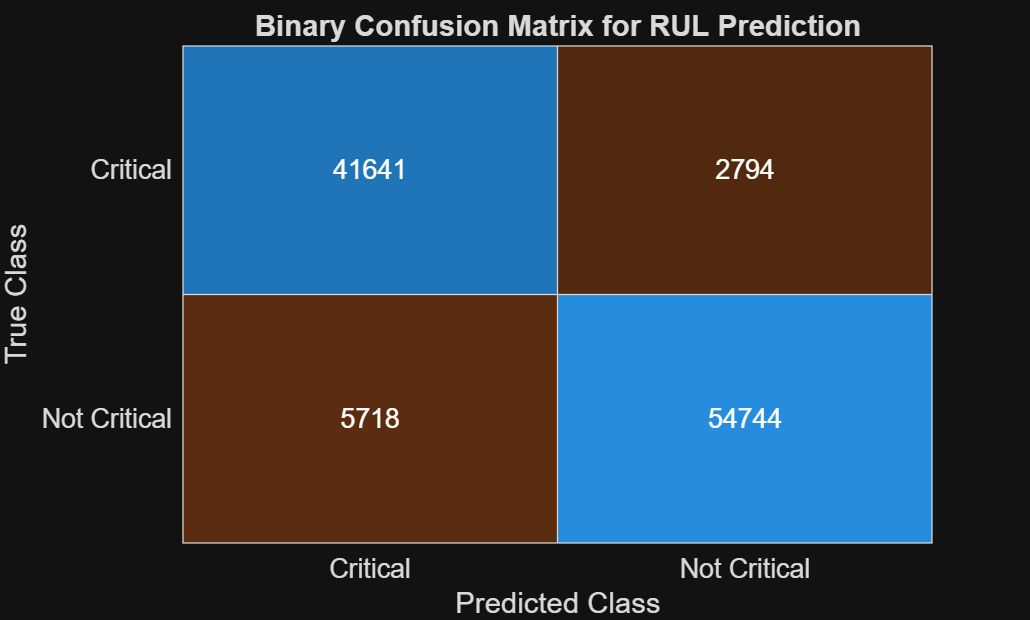


% Plot confusion matrix
figure;
confusionchart(confMat, {'Critical','Not Critical'});
title('Binary Confusion Matrix for RUL Prediction');



accuracy  = (TP + TN) / (TP + TN + FP + FN);
precision = TP / (TP + FP + eps);
recall    = TP / (TP + FN + eps);

fprintf("\nAccuracy  : %.4f\n", accuracy);


Accuracy  : 0.9072


fprintf("Precision : %.4f\n", precision);

Precision : 0.9527


fprintf("Recall    : %.4f\n", recall);

Recall    : 0.9139
